clear all
d1=load("E:\MTP2\LM_bin_1_lag\ppt_vod_bin_1lag.mat");
d2=load("E:\MTP2\LM_bin_1_lag\ppt_vod_c_bin_1lag.mat");
d3=load("E:\MTP2\LM_bin_1_lag\ppt_vod_x_bin_1lag.mat");
d4=load("E:\MTP2\LM_bin_1_lag\ppt_sif_bin_1lag.mat");
d5=load("E:\MTP2\LM_bin_2_lag\ppt_vod_bin_2lag.mat");
d6=load("E:\MTP2\LM_bin_2_lag\ppt_vod_c_bin_2lag.mat");
d7=load("E:\MTP2\LM_bin_2_lag\ppt_vod_x_bin_2lag.mat");
d8=load("E:\MTP2\LM_bin_2_lag\ppt_sif_bin_2lag.mat");
d9=load("E:\MTP2\LM_bin_3_lag\ppt_vod_bin_3lag.mat");
d10=load("E:\MTP2\LM_bin_3_lag\ppt_vod_c_bin_3lag.mat");
d11=load("E:\MTP2\LM_bin_3_lag\ppt_vod_x_bin_3lag.mat");
d12=load("E:\MTP2\LM_bin_3_lag\ppt_sif_bin_3lag.mat");

z_r=d12.res(:,:,3);
z_s=d12.res(:,:,1);

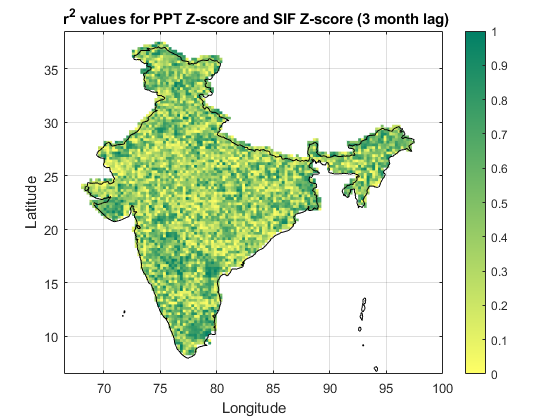

data=z_r;
trial=data(:,:,1);
lat=data(2:130,1,1);
lon=data(1,2:136,1)';
crop1=(data(2:130,2:136,1));
f=figure(1);
%cropf_slope=fliplr(flipud(crop1));
%J(2:130,2:136,1)=fliplr(flipud(crop1));
%slp=pcolor(lon,lat,flipud(cropf_slope));
slp=pcolor(lon,lat,crop1);
slp.EdgeColor='none';
xlabel('Longitude'); % Labelling x axis 
ylabel('Latitude'); % Labelling y axis
title(' r^2 values for PPT Z-score and SIF Z-score (3 month lag)'); % Putting title to the figure
colormap(flipud(summer)) % Setting a color scheme
hcb1=colorbar; % Showing the scheme on a scale
caxis([0 1])
%title(hcb1,'(in m3/m3)') % Titling a colorbar
grid on % Showing grid lines
hold on % Starting a new plot on same figure retaining the former
geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); % Plotting shapefile of India - you should have a .shp shapefile
% saveas(f,"E:\MTP2\MTP2 final results\slope and r2 maps\vod\r2 PPT_VOD 3lag.jpg");
% saveas(f,"E:\MTP2\MTP2 final results\slope and r2 maps\vod-c\r2 PPT_VOD-C 3lag.jpg");
% saveas(f,"E:\MTP2\MTP2 final results\slope and r2 maps\vod-x\r2 PPT_VOD-X 3lag.jpg");
saveas(f,"E:\MTP2\MTP2 final results\slope and r2 maps\sif\r2 PPT_SIF 3lag.jpg");

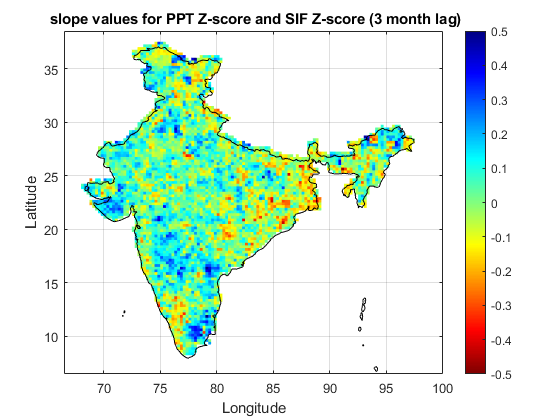

data=z_s;
trial=data(:,:,1);
lat=data(2:130,1,1);
lon=data(1,2:136,1)';
crop1=(data(2:130,2:136,1));
f=figure(2);
%cropf_slope=fliplr(flipud(crop1));
%J(2:130,2:136,1)=fliplr(flipud(crop1));
%slp=pcolor(lon,lat,flipud(cropf_slope));
slp=pcolor(lon,lat,crop1);
slp.EdgeColor='none';
xlabel('Longitude'); % Labelling x axis 
ylabel('Latitude'); % Labelling y axis
title(' slope values for PPT Z-score and SIF Z-score (3 month lag)'); % Putting title to the figure
colormap(flipud(jet)) % Setting a color scheme
hcb1=colorbar; % Showing the scheme on a scale
caxis([-0.5 0.5])
%title(hcb1,'(in m3/m3)') % Titling a colorbar
grid on % Showing grid lines
hold on % Starting a new plot on same figure retaining the former
geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); % Plotting shapefile of India - you should have a .shp shapefile
% saveas(f,"E:\MTP2\MTP2 final results\slope and r2 maps\vod\slope PPT_VOD 3lag.jpg");
% saveas(f,"E:\MTP2\MTP2 final results\slope and r2 maps\vod-c\slope PPT_VOD-C 3lag.jpg");
% saveas(f,"E:\MTP2\MTP2 final results\slope and r2 maps\vod-x\slope PPT_VOD-X 3lag.jpg");
saveas(f,"E:\MTP2\MTP2 final results\slope and r2 maps\sif\slope PPT_SIF 3lag.jpg");

%  
